# Parte II - Problema 2

#### Começamos por fazer o gráfico das aproximações de $\hat{y(x_i)}$ para $x\in[0,2]$ sendo $x_i = 0.001\times i$. 

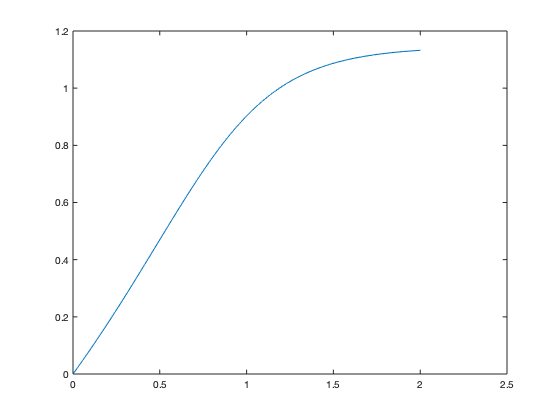

h = 0.001;
a = 2;
[x,y] = p2ex1(a,h);
plot(x,y)

table(x,y)

ans = 2002×2 table
      x               y          
    _____    ____________________

        0                       0
    0.001    0.000841698255726796
    0.002     0.00168385119133362
    0.003     0.00252645883645738
    0.004     0.00336952121888272
    0.005     0.00421303836453191
    0.006     0.00505701029745478
    0.007     0.00590143703981855
    0.008     0.00674631861189767
    0.009     0.00759165503206355
     0.01     0.00843744631677438
    0.011     0.00928369248056475
    0.012      0.0101303935360353
    0.013      0.0109775494938426
    0.014      0.0118251603626882
    0.015      0.0126732261493088


#### Temos os pontos consecutivos $(1.18799999999998, 0.999643920093033)$ e $(1.18899999999998,1.00005507357204)$. Somos, portanto, tentados a encontrar, por interpolação linear, $z$ tal que $y(z) = 1$ no intervalo $[1.18799999999998,1.18899999999998]$ de modo que teríamos certamente um erro menor que $10^{-3}$. No entanto, não podemos assim fazer pois há erros associados aos valores de $y$ devido ao método de Heun.   

#### Por exemplo, poderíamos ter que o valor real do primeiro ponto é maior que 1, i.e. $y(1.18799999999998) > 1$. Isso seria suficiente para tornar inválida a nossa estimativa.

#### No entanto, sabendo o erro do método de Heun seremos capazes de comparar a lista das 'estimações - erro' ($\hat{y(x_i)} - e_{y(x_i)}$) com a lista das 'estimações + erro' ($\hat{y(x_i)} + e_{y(x_i)}$), para assim ter valores confiáveis e, então, fazer a interpolação linear.

#### Para calcular o erro global do método de Heun, primeiramente, devemos notar que o método é de segunda ordem, i.e. o erro é proporcional ao quadrado do passo ($|e_{y(x_i)}| \leq C*h^2$). Sendo assim, ao dividir $h$ por $2$, a majoração do erro reduz-se em $1/4$. Isso posto, iremos calcular $\hat{y(2)}$ para valores de $h$ consecutivamente menores ( no caso $h_{i+1} = \frac{h_i}{2}$) e tomaremos em conta a seguinte equação

                                                            
$$| \hat{y(x_i)} - y(x_i) | \approx C h_i^2 $$


#### da qual deduz-se

                                                            
$$C \approx \frac{\hat{y(x_{i+1})}  - \hat{y(x_i)} }{ h_{i+1}^2 - h_{i}^2}$$


#### para estimar $C$.

[T] = p2ex2C(2);
T

T = 20×3 table
           h              aproximacao               C         
    ________________    ________________    __________________

                 0.1    1.13158427200071    0.0871258396114053
                0.05    1.13223771579779    0.0753965460541887
               0.025    1.13237908432165    0.0706275931359338
              0.0125    1.13241219100593    0.0684675198272089
             0.00625    1.13242021454341    0.0674383812035254
            0.003125    1.13242219027723    0.0669359398064747
           0.0015625     1.1324226805307    0.0666876806159659
          0.00078125    1.13242280263949    0.0665642747965952
         0.000390625    1.13242283311019    0.0665027648210525
        0.0001953125    1.13242284072083    0.0664721165473262
        9.765625e-05    1.13242284262261    0.0664569127062956
       4.8828125e-05    1.13242284309795    0.0664519766966502


#### Por segurança, podemos tomar o maior valor de $C$calculado, ou seja $0.0871258396114053$. 

#### Prosseguimos, agora, ao cálculo das estimações $\pm$ erro global.

y_menos_erro = y-(0.0871258396114053*0.001*0.001);
y_mais_erro  = y+(0.0871258396114053*0.001*0.001);
table(x,y,y_menos_erro,y_mais_erro)

ans = 2002×4 table
      x               y                  y_menos_erro             y_mais_erro     
    _____    ____________________    _____________________    ____________________

        0                       0    -8.71258396114053e-08    8.71258396114053e-08
    0.001    0.000841698255726796     0.000841611129887185    0.000841785381566407
    0.002     0.00168385119133362      0.00168376406549401     0.00168393831717323
    0.003     0.00252645883645738      0.00252637171061777     0.00252654596229699
    0.004     0.00336952121888272      0.00336943409304311     0.00336960834472233
    0.005     0.00421303836453191       0.0042129512386923     0.00421312549037152
    0.006     0.00505701029745478      0.00505692317161517     0.00505709742329439
    0.007     0.00590143703981855      0.00590134991397894     0.00590152416565817
    0.008     

#### O maior $x_i$ tal que $\hat{y(x_i)} + e_{y(x_i)} < 1$ é $1.18799999999998$. O menor $x_i$ tal que $\hat{y(x_i)} - e_{y(x_i)} > 1$ é $1.18899999999998$. Portanto, concluimos que $y(1.18799999999998) < 1$ e $y(1.18899999999998) > 1$ (valores reais). Logo, $z \in [1.18799999999998, 1.18899999999998]$ e $e_z \leq 10^{-3}$.

#### Para estimarmos $z$ iremos utilizar interpolação linear com os dois extremos do intervalo. O polinómio interpolador é a recta


$$y = \frac{(1.000055073572044 - 0.999643920093033)}{(1.18899999999998 - 1.18799999999998)} * (x- 1.18799999999998) + 0.999643920093033$$


#### Tomando $y = 1$, temos $\hat{z} = 1.188866051061553$.